# Machine Learning: Programming Exercise 2 

## Logistic Regression

In this exercise, you will implement logistic regression and apply it to two different datasets.

### Files needed for this exercise

- `ex2.mlx` - MATLAB Live Script that steps you through the exercise

- ex2data1.txt - Training set for the first half of the exercise

- ex2data2.txt - Training set for the second half of the exercise

- `submit.m` - Submission script that sends your solutions to our servers

- `mapFeature.m` - Function to generate polynomial features

- `plotDecisionBoundary.m` - Function to plot classifier's decision boundary

- *`plotData.m` - Function to plot 2D classification data

- *`sigmoid.m` - Sigmoid function

- *`costFunction.m` - Logistic regression cost function

- *`predict.m` - Logistic regression prediction function

- `*costFunctionReg.m` - Regularized logistic regression cost function

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex2' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir


.                       costFunction.m          ex2.mlx                 ex2data1.txt            lib                     plotData.m              predict.m               submit.m                
..                      costFunctionReg.m       ex2_companion.mlx       ex2data2.txt            mapFeature.m            plotDecisionBoundary.m  sigmoid.m               



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Logistic Regression

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. Suppose that you are the administrator of a university department and you want to determine each applicant's chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant's scores on two exams and the admissions decision.

    Your task is to build a classification model that estimates an applicant's probability of admission based the scores from those two exams. `ex2.mlx` will guide you through the exercise. To begin, run the code below to load the data into MATLAB.

% Load Data
% The first two columns contain the exam scores and the third column contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

### 1.1 Visualizing the data

Before starting to implement any learning algorithm, it is always good to visualize the data if possible. The code below will load the data and display it on a 2-dimensional plot by calling the function `plotData`. You will now complete the code in `plotData` so that it displays a figure like Figure 1, where the axes are the two exam scores, and the positive and negative examples are shown with different markers.

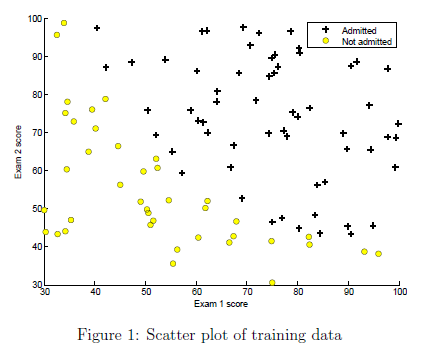

To help you get more familiar with plotting, we have left `plotData.m` empty so you can try to implement it yourself. However, this is an optional (ungraded) exercise. We also provide our implementation below so you can copy it or refer to it. If you choose to copy our example, make sure you learn what each of its commands is doing by consulting the MATLAB documentation.

Once you have added your own or the above code to `plotData.m`, run the code in this section to call the `plotData` function.

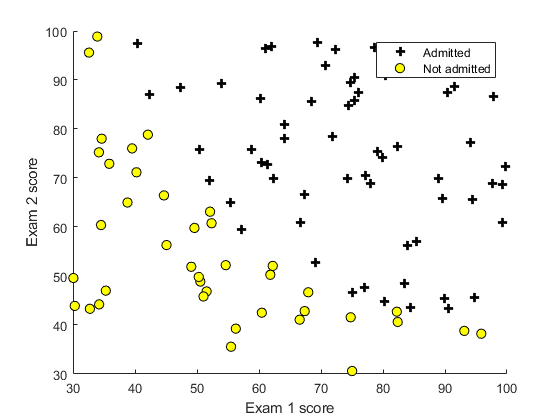

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);
 
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Warmup exercise: sigmoid function

Before you start with the actual cost function, recall that the logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


    Your first step is to implement this function in `sigmoid.m` so it can be called by the rest of your program. When you are finished, try testing a few values by calling `sigmoid(x)` in the code section below. For large positive values of `x`, the sigmoid should be close to 1, while for large negative values, the sigmoid should be close to 0. Evaluating `sigmoid(0)` should give you exactly 0.5. **Your code should also work with vectors and matrices**. For a matrix, your function should perform the sigmoid function on every element.

% Provide input values to the sigmoid function below and run to check your implementation
sigmoid(0)

     0



ans = 0.5000

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Cost function and gradient

Now you will implement the cost function and gradient for logistic regression. Complete the code in `costFunction.m` to return the cost and gradient. Recall that the cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


Note that while this gradient looks identical to the linear regression gradient, the formula is actually different because linear and logistic regression have different definitions of $h_{\theta}(x)$. Once you are done, run the code sections below to set up your data and call your `costFunction` using the initial parameters of $\theta$. You should see that the cost is about 0.693 and gradients of about -0.1000,  -12.0092, and -11.2628

%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];

% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); disp(grad);

Gradient at initial theta (zeros):
   -0.1000
  -12.0092
  -11.2628



#### 1.2.3 Learning parameters using `fminunc`

In the previous assignment, you found the optimal parameters of a linear regression model by implementing gradent descent. You wrote a cost function and calculated its gradient, then took a gradient descent step accordingly. This time, instead of taking gradient descent steps, you will use a MATLAB built-in function called `fminunc`. 

    MATLAB's `fminunc` is an optimization solver that finds the minimum of an unconstrained* function. For logistic regression, you want to optimize the cost function $J(\theta)$ with parameters. Concretely, you are going to use `fminunc` to find the best parameters $\theta$ for the logistic regression cost function, given a fixed dataset (of $X$ and $y$ values). You will pass to `fminunc` the following inputs:

- The initial values of the parameters we are trying to optimize.

- A function that, when given the training set and a particular $\theta$ computes the logistic regression cost and gradient with respect to $\theta$ for the dataset $(X, y)$

**Constraints in optimization often refer to constraints on the parameters, for example, constraints that bound the possible values *$\theta$* can take (e.g. *$\theta<1$*). Logistic regression does not have such constraints since *$\theta$* is allowed to take any real value.*

We already have code written below to call `fminunc` with the correct arguments:

- We first define the options to be used with `fminunc`. Specically, we set the `GradObj` option to `on`, which tells `fminunc` that our function returns both the cost and the gradient. This allows `fminunc` to use the gradient when minimizing the function. 

- Furthermore, we set the `MaxIter` option to 400, so that `fminunc` will run for at most 400 steps before it terminates. 

- To specify the actual function we are minimizing, we use a 'short-hand' for specifying functions with: `@(t)(costFunction(t,X,y))`. This creates a function, with argument `t`, which calls your `costFunction`. This allows us to wrap the `costFunction` for use with `fminunc`.

- If you have completed the `costFunction` correctly, `fminunc` will converge on the right optimization parameters and return the final values of the cost and $\theta$. Notice that by using `fminunc`, you did not have to write any loops yourself, or set a learning rate like you did for gradient descent. This is all done by `fminunc`: you only needed to provide a function calculating the cost and the gradient.

- Once `fminunc` completes, the remaining code will call your `costFunction` function using the optimal parameters of $\theta$. You should see that the cost is about 0.203. This final $\theta$ value will then be used to plot the decision boundary on the training data, resulting in a figure similar to Figure 2. We also encourage you to look at the code in `plotDecisionBoundary.m` to see how to plot such a boundary using the $\theta$ values.

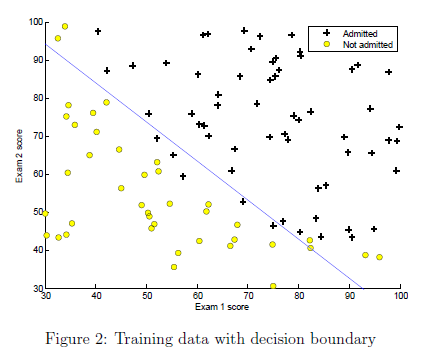

Run the code below and verify the results.

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



h =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


  107.8074
   71.4620
  104.2271
  141.1354
  149.7028
   97.9079
  151.6282
  118.6937
  158.0945
  125.2689
  131.7195
  103.7233
  154.0440
  161.0184
  110.8578
  137.6425
  118.5411
  111.7327
  157.8215
  121.6062
  107.5564
  151.3950
   96.3625
   75.6823
  142.6181
  127.8861
  122.2345
  129.5119
  108.9712
   99.7503
  129.6705
  138.9190
  111.3205
  117.1713
  106.9899
  103.6122
  126.6485
  140.0649
  113.7872
  104.7537
  136.7192
   95.5002
  155.9455
  120.4709
   94.0309
  111.0564
  143.2806
  179.1176
  152.8360
  174.7571
  149.5070
  156.4888
  131.2489
   91.1755
   97.0040
  105.6868
  162.2358
  122.2426
  139.7420
  145.3825
  155.8339
   79.3926
   93.0835
   76.5779
  106.9968
  105.1074
  131.9392
   97.7396
  166.6789
  123.9558
   73.3468
  137.2297
  162.6019
  129.0183
  129.9931
  167.7077
  130.2497
  121.5648
  100.3304
  122.2998
  154.3877
  137.6972
  129.7784
  113.0625
  165.6820
  148.7515
  116.0284
  160.2907
  169.2845
  109.3490
  166.4663

h =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


   53.9037
   35.7310
   52.1135
   70.5677
   74.8514
   48.9540
   75.8141
   59.3469
   79.0472
   62.6345
   65.8597
   51.8616
   77.0220
   80.5092
   55.4289
   68.8212
   59.2706
   55.8663
   78.9108
   60.8031
   53.7782
   75.6975
   48.1813
   37.8411
   71.3091
   63.9431
   61.1172
   64.7560
   54.4856
   49.8752
   64.8352
   69.4595
   55.6603
   58.5857
   53.4949
   51.8061
   63.3243
   70.0325
   56.8936
   52.3768
   68.3596
   47.7501
   77.9727
   60.2355
   47.0154
   55.5282
   71.6403
   89.5588
   76.4180
   87.3786
   74.7535
   78.2444
   65.6245
   45.5878
   48.5020
   52.8434
   81.1179
   61.1213
   69.8710
   72.6912
   77.9169
   39.6963
   46.5418
   38.2890
   53.4984
   52.5537
   65.9696
   48.8698
   83.3395
   61.9779
   36.6734
   68.6148
   81.3009
   64.5092
   64.9966
   83.8538
   65.1248
   60.7824
   50.1652
   61.1499
   77.1938
   68.8486
   64.8892
   56.5312
   82.8410
   74.3757
   58.0142
   80.1453
   84.6423
   54.6745
   83.2332

h =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


    3.3690
    2.2332
    3.2571
    4.4105
    4.6782
    3.0596
    4.7384
    3.7092
    4.9405
    3.9147
    4.1162
    3.2414
    4.8139
    5.0318
    3.4643
    4.3013
    3.7044
    3.4916
    4.9319
    3.8002
    3.3611
    4.7311
    3.0113
    2.3651
    4.4568
    3.9964
    3.8198
    4.0472
    3.4054
    3.1172
    4.0522
    4.3412
    3.4788
    3.6616
    3.3434
    3.2379
    3.9578
    4.3770
    3.5559
    3.2736
    4.2725
    2.9844
    4.8733
    3.7647
    2.9385
    3.4705
    4.4775
    5.5974
    4.7761
    5.4612
    4.6721
    4.8903
    4.1015
    2.8492
    3.0314
    3.3027
    5.0699
    3.8201
    4.3669
    4.5432
    4.8698
    2.4810
    2.9089
    2.3931
    3.3436
    3.2846
    4.1231
    3.0544
    5.2087
    3.8736
    2.2921
    4.2884
    5.0813
    4.0318
    4.0623
    5.2409
    4.0703
    3.7989
    3.1353
    3.8219
    4.8246
    4.3030
    4.0556
    3.5332
    5.1776
    4.6485
    3.6259
    5.0091
    5.2901
    3.4172
    5.2021

h =     0.9667
    0.9032
    0.9629
    0.9880
    0.9908
    0.9552
    0.9913
    0.9761
    0.9929
    0.9804


    0.6393
    0.4238
    0.6181
    0.8370
    0.8878
    0.5806
    0.8992
    0.7039
    0.9375
    0.7429
    0.7811
    0.6151
    0.9135
    0.9549
    0.6574
    0.8163
    0.7030
    0.6626
    0.9359
    0.7212
    0.6378
    0.8978
    0.5715
    0.4488
    0.8458
    0.7584
    0.7249
    0.7680
    0.6462
    0.5915
    0.7690
    0.8238
    0.6602
    0.6949
    0.6345
    0.6144
    0.7511
    0.8306
    0.6748
    0.6212
    0.8108
    0.5663
    0.9248
    0.7144
    0.5576
    0.6586
    0.8497
    1.0622
    0.9064
    1.0363
    0.8866
    0.9280
    0.7783
    0.5407
    0.5753
    0.6267
    0.9621
    0.7249
    0.8287
    0.8622
    0.9241
    0.4708
    0.5520
    0.4541
    0.6345
    0.6233
    0.7824
    0.5796
    0.9884
    0.7351
    0.4350
    0.8138
    0.9643
    0.7651
    0.7709
    0.9945
    0.7724
    0.7209
    0.5950
    0.7253
    0.9156
    0.8166
    0.7696
    0.6705
    0.9825
    0.8821
    0.6881
    0.9506
    1.0039
    0.6485
    0.9872

h =     0.6546
    0.6044
    0.6498
    0.6978
    0.7084
    0.6412
    0.7108
    0.6690
    0.7186
    0.6776


    0.5975
    0.3988
    0.5786
    0.7878
    0.8414
    0.5478
    0.8451
    0.6717
    0.8858
    0.7109
    0.7502
    0.5905
    0.8661
    0.8991
    0.6159
    0.7666
    0.6687
    0.6313
    0.8822
    0.6882
    0.6085
    0.8545
    0.5414
    0.4232
    0.8025
    0.7168
    0.6929
    0.7372
    0.6140
    0.5554
    0.7261
    0.7853
    0.6231
    0.6548
    0.5952
    0.5823
    0.6994
    0.7835
    0.6450
    0.5808
    0.7728
    0.5371
    0.8810
    0.6841
    0.5290
    0.6255
    0.8058
    1.0079
    0.8520
    0.9819
    0.8406
    0.8858
    0.7456
    0.5073
    0.5448
    0.5916
    0.9163
    0.6750
    0.7856
    0.8152
    0.8732
    0.4437
    0.5258
    0.4265
    0.5969
    0.5949
    0.7306
    0.5484
    0.9339
    0.6971
    0.4100
    0.7681
    0.9088
    0.7222
    0.7269
    0.9468
    0.7240
    0.6781
    0.5667
    0.6940
    0.8705
    0.7822
    0.7289
    0.6345
    0.9285
    0.8322
    0.6449
    0.8974
    0.9474
    0.6125
    0.9379

h =     0.6451
    0.5984
    0.6407
    0.6874
    0.6988
    0.6336
    0.6995
    0.6619
    0.7080
    0.6706


    0.5681
    0.3841
    0.5516
    0.7590
    0.8207
    0.5299
    0.8118
    0.6635
    0.8592
    0.7056
    0.7493
    0.5895
    0.8456
    0.8667
    0.5882
    0.7354
    0.6566
    0.6218
    0.8522
    0.6799
    0.6006
    0.8401
    0.5279
    0.4090
    0.7846
    0.6957
    0.6863
    0.7355
    0.6018
    0.5326
    0.7036
    0.7740
    0.6034
    0.6323
    0.5698
    0.5680
    0.6604
    0.7578
    0.6390
    0.5525
    0.7616
    0.5247
    0.8675
    0.6798
    0.5169
    0.6125
    0.7871
    0.9853
    0.8188
    0.9574
    0.8207
    0.8751
    0.7415
    0.4858
    0.5308
    0.5730
    0.9018
    0.6373
    0.7666
    0.7920
    0.8473
    0.4284
    0.5176
    0.4091
    0.5744
    0.5876
    0.6933
    0.5332
    0.9059
    0.6809
    0.3959
    0.7437
    0.8776
    0.6994
    0.7026
    0.9311
    0.6919
    0.6523
    0.5577
    0.6887
    0.8541
    0.7777
    0.7103
    0.6173
    0.9010
    0.8052
    0.6163
    0.8694
    0.9171
    0.5939
    0.9191

h =     0.6383
    0.5949
    0.6345
    0.6811
    0.6944
    0.6295
    0.6925
    0.6600
    0.7025
    0.6694


    0.5000
    0.3551
    0.4911
    0.7028
    0.7948
    0.4983
    0.7436
    0.6702
    0.8155
    0.7244
    0.7847
    0.6163
    0.8211
    0.8042
    0.5269
    0.6701
    0.6504
    0.6222
    0.7969
    0.6871
    0.6053
    0.8355
    0.5104
    0.3831
    0.7657
    0.6619
    0.6997
    0.7679
    0.5924
    0.4845
    0.6655
    0.7767
    0.5694
    0.5902
    0.5153
    0.5498
    0.5655
    0.7119
    0.6518
    0.4876
    0.7639
    0.5106
    0.8673
    0.7005
    0.5037
    0.6012
    0.7658
    0.9615
    0.7511
    0.9256
    0.7971
    0.8849
    0.7658
    0.4398
    0.5119
    0.5409
    0.9003
    0.5453
    0.7435
    0.7558
    0.8051
    0.3999
    0.5172
    0.3728
    0.5297
    0.5939
    0.6057
    0.5106
    0.8600
    0.6623
    0.3698
    0.7013
    0.8195
    0.6601
    0.6584
    0.9271
    0.6217
    0.6009
    0.5569
    0.7066
    0.8438
    0.8029
    0.6851
    0.5923
    0.8567
    0.7571
    0.5537
    0.8214
    0.8640
    0.5630
    0.9040

h =     0.6225
    0.5879
    0.6204
    0.6688
    0.6889
    0.6221
    0.6778
    0.6616
    0.6933
    0.6736


    0.4221
    0.3286
    0.4239
    0.6521
    0.7933
    0.4745
    0.6769
    0.7115
    0.7886
    0.7861
    0.8739
    0.6849
    0.8229
    0.7487
    0.4604
    0.6044
    0.6714
    0.6518
    0.7517
    0.7297
    0.6406
    0.8675
    0.5082
    0.3624
    0.7733
    0.6425
    0.7523
    0.8516
    0.6060
    0.4356
    0.6398
    0.8168
    0.5452
    0.5552
    0.4582
    0.5484
    0.4508
    0.6769
    0.7012
    0.4137
    0.8028
    0.5134
    0.9074
    0.7638
    0.5075
    0.6124
    0.7696
    0.9708
    0.6855
    0.9215
    0.7991
    0.9407
    0.8375
    0.3919
    0.5076
    0.5184
    0.9400
    0.4340
    0.7437
    0.7373
    0.7799
    0.3761
    0.5406
    0.3362
    0.4878
    0.6308
    0.5039
    0.5008
    0.8318
    0.6655
    0.3483
    0.6709
    0.7715
    0.6324
    0.6234
    0.9643
    0.5464
    0.5524
    0.5815
    0.7661
    0.8677
    0.8777
    0.6797
    0.5826
    0.8306
    0.7210
    0.4865
    0.7883
    0.8254
    0.5433
    0.9237

h =     0.6040
    0.5814
    0.6044
    0.6575
    0.6885
    0.6164
    0.6630
    0.6707
    0.6875
    0.6870


    0.3779
    0.3210
    0.3882
    0.6384
    0.8239
    0.4747
    0.6516
    0.7723
    0.7990
    0.8659
    0.9789
    0.7661
    0.8573
    0.7352
    0.4266
    0.5770
    0.7148
    0.7012
    0.7464
    0.7924
    0.6939
    0.9273
    0.5267
    0.3606
    0.8102
    0.6530
    0.8237
    0.9514
    0.6410
    0.4147
    0.6452
    0.8809
    0.5481
    0.5499
    0.4317
    0.5693
    0.3788
    0.6765
    0.7680
    0.3724
    0.8655
    0.5361
    0.9752
    0.8440
    0.5307
    0.6456
    0.8034
    1.0169
    0.6615
    0.9552
    0.8326
    1.0220
    0.9274
    0.3700
    0.5246
    0.5214
    1.0087
    0.3641
    0.7736
    0.7522
    0.7913
    0.3725
    0.5806
    0.3209
    0.4745
    0.6850
    0.4442
    0.5132
    0.8429
    0.6946
    0.3453
    0.6740
    0.7647
    0.6360
    0.6208
    1.0320
    0.5092
    0.5364
    0.6241
    0.8434
    0.9212
    0.9714
    0.7026
    0.5983
    0.8433
    0.7215
    0.4532
    0.7939
    0.8281
    0.5496
    0.9762

h =     0.5934
    0.5796
    0.5959
    0.6544
    0.6951
    0.6165
    0.6574
    0.6840
    0.6898
    0.7039


    0.3820
    0.3289
    0.3939
    0.6543
    0.8516
    0.4881
    0.6663
    0.8030
    0.8231
    0.9020
    1.0218
    0.7995
    0.8865
    0.7539
    0.4336
    0.5892
    0.7413
    0.7281
    0.7667
    0.8239
    0.7212
    0.9622
    0.5443
    0.3705
    0.8385
    0.6730
    0.8573
    0.9929
    0.6641
    0.4233
    0.6641
    0.9151
    0.5639
    0.5646
    0.4400
    0.5884
    0.3789
    0.6955
    0.7995
    0.3768
    0.8991
    0.5546
    1.0126
    0.8795
    0.5491
    0.6687
    0.8310
    1.0523
    0.6766
    0.9870
    0.8610
    1.0628
    0.9667
    0.3772
    0.5418
    0.5366
    1.0472
    0.3641
    0.7997
    0.7756
    0.8153
    0.3825
    0.6028
    0.3277
    0.4859
    0.7123
    0.4479
    0.5294
    0.8683
    0.7185
    0.3545
    0.6934
    0.7852
    0.6544
    0.6379
    1.0711
    0.5180
    0.5492
    0.6480
    0.8785
    0.9550
    1.0126
    0.7257
    0.6175
    0.8690
    0.7419
    0.4611
    0.8171
    0.8519
    0.5660
    1.0114

h =     0.5944
    0.5815
    0.5972
    0.6580
    0.7009
    0.6197
    0.6607
    0.6906
    0.6949
    0.7114


    0.3906
    0.3335
    0.4019
    0.6634
    0.8590
    0.4940
    0.6766
    0.8071
    0.8320
    0.9055
    1.0245
    0.8017
    0.8940
    0.7642
    0.4419
    0.5988
    0.7462
    0.7323
    0.7764
    0.8281
    0.7250
    0.9683
    0.5491
    0.3751
    0.8452
    0.6801
    0.8611
    0.9957
    0.6689
    0.4303
    0.6716
    0.9202
    0.5704
    0.5719
    0.4477
    0.5935
    0.3901
    0.7039
    0.8030
    0.3851
    0.9041
    0.5591
    1.0186
    0.8827
    0.5535
    0.6736
    0.8379
    1.0607
    0.6869
    0.9958
    0.8682
    1.0681
    0.9700
    0.3838
    0.5468
    0.5427
    1.0535
    0.3748
    0.8066
    0.7836
    0.8240
    0.3874
    0.6063
    0.3330
    0.4929
    0.7159
    0.4587
    0.5346
    0.8777
    0.7244
    0.3591
    0.7015
    0.7953
    0.6620
    0.6458
    1.0777
    0.5277
    0.5572
    0.6518
    0.8819
    0.9615
    1.0161
    0.7323
    0.6235
    0.8783
    0.7508
    0.4697
    0.8264
    0.8618
    0.5722
    1.0187

h =     0.5964
    0.5826
    0.5991
    0.6600
    0.7024
    0.6210
    0.6630
    0.6915
    0.6968
    0.7121


    0.3944
    0.3352
    0.4052
    0.6668
    0.8609
    0.4959
    0.6805
    0.8073
    0.8348
    0.9052
    1.0234
    0.8009
    0.8958
    0.7680
    0.4453
    0.6025
    0.7470
    0.7328
    0.7797
    0.8283
    0.7252
    0.9692
    0.5503
    0.3766
    0.8467
    0.6823
    0.8610
    0.9947
    0.6698
    0.4330
    0.6740
    0.9207
    0.5726
    0.5744
    0.4508
    0.5949
    0.3952
    0.7067
    0.8028
    0.3886
    0.9046
    0.5602
    1.0193
    0.8823
    0.5545
    0.6747
    0.8396
    1.0627
    0.6908
    0.9981
    0.8700
    1.0683
    0.9695
    0.3863
    0.5481
    0.5447
    1.0543
    0.3798
    0.8083
    0.7859
    0.8267
    0.3891
    0.6068
    0.3350
    0.4956
    0.7160
    0.4635
    0.5362
    0.8807
    0.7259
    0.3606
    0.7041
    0.7988
    0.6644
    0.6485
    1.0787
    0.5316
    0.5602
    0.6523
    0.8816
    0.9627
    1.0155
    0.7341
    0.6252
    0.8811
    0.7537
    0.4732
    0.8294
    0.8652
    0.5742
    1.0202

h =     0.5973
    0.5830
    0.5999
    0.6608
    0.7028
    0.6215
    0.6639
    0.6915
    0.6974
    0.7120


    0.4035
    0.3392
    0.4134
    0.6747
    0.8652
    0.5005
    0.6901
    0.8073
    0.8414
    0.9038
    1.0200
    0.7983
    0.9000
    0.7769
    0.4536
    0.6116
    0.7487
    0.7336
    0.7878
    0.8283
    0.7254
    0.9709
    0.5532
    0.3803
    0.8501
    0.6874
    0.8602
    0.9917
    0.6718
    0.4396
    0.6797
    0.9215
    0.5775
    0.5804
    0.4582
    0.5978
    0.4078
    0.7134
    0.8021
    0.3973
    0.9054
    0.5626
    1.0205
    0.8806
    0.5568
    0.6769
    0.8433
    1.0671
    0.7003
    1.0034
    0.8741
    1.0683
    0.9675
    0.3926
    0.5511
    0.5494
    1.0558
    0.3920
    0.8122
    0.7915
    0.8331
    0.3931
    0.6074
    0.3400
    0.5018
    0.7160
    0.4753
    0.5396
    0.8876
    0.7291
    0.3642
    0.7103
    0.8072
    0.6702
    0.6549
    1.0805
    0.5412
    0.5674
    0.6531
    0.8803
    0.9652
    1.0135
    0.7382
    0.6290
    0.8879
    0.7608
    0.4817
    0.8366
    0.8730
    0.5787
    1.0234

h =     0.5995
    0.5840
    0.6019
    0.6626
    0.7038
    0.6226
    0.6660
    0.6915
    0.6988
    0.7117


    0.4161
    0.3445
    0.4247
    0.6858
    0.8712
    0.5067
    0.7034
    0.8072
    0.8505
    0.9017
    1.0152
    0.7945
    0.9058
    0.7893
    0.4651
    0.6241
    0.7508
    0.7344
    0.7989
    0.8281
    0.7255
    0.9733
    0.5569
    0.3852
    0.8548
    0.6944
    0.8590
    0.9874
    0.6743
    0.4487
    0.6875
    0.9224
    0.5844
    0.5887
    0.4685
    0.6018
    0.4253
    0.7227
    0.8009
    0.4094
    0.9063
    0.5657
    1.0222
    0.8782
    0.5598
    0.6798
    0.8484
    1.0731
    0.7135
    1.0108
    0.8797
    1.0683
    0.9645
    0.4012
    0.5551
    0.5558
    1.0577
    0.4089
    0.8176
    0.7992
    0.8420
    0.3984
    0.6082
    0.3467
    0.5104
    0.7158
    0.4916
    0.5442
    0.8973
    0.7334
    0.3691
    0.7190
    0.8189
    0.6782
    0.6637
    1.0830
    0.5545
    0.5774
    0.6540
    0.8783
    0.9686
    1.0105
    0.7437
    0.6343
    0.8973
    0.7705
    0.4935
    0.8465
    0.8839
    0.5850
    1.0277

h =     0.6026
    0.5853
    0.6046
    0.6650
    0.7050
    0.6240
    0.6689
    0.6915
    0.7007
    0.7113


    0.4377
    0.3533
    0.4439
    0.7049
    0.8816
    0.5171
    0.7264
    0.8069
    0.8665
    0.8980
    1.0068
    0.7878
    0.9159
    0.8110
    0.4848
    0.6459
    0.7543
    0.7358
    0.8183
    0.8278
    0.7254
    0.9774
    0.5631
    0.3932
    0.8629
    0.7064
    0.8569
    0.9798
    0.6785
    0.4641
    0.7009
    0.9239
    0.5960
    0.6029
    0.4861
    0.6084
    0.4555
    0.7387
    0.7986
    0.4300
    0.9079
    0.5709
    1.0251
    0.8738
    0.5646
    0.6846
    0.8573
    1.0839
    0.7364
    1.0237
    0.8894
    1.0683
    0.9594
    0.4157
    0.5617
    0.5666
    1.0613
    0.4381
    0.8269
    0.8125
    0.8574
    0.4074
    0.6092
    0.3578
    0.5250
    0.7152
    0.5197
    0.5520
    0.9142
    0.7408
    0.3772
    0.7339
    0.8392
    0.6919
    0.6790
    1.0874
    0.5775
    0.5945
    0.6554
    0.8748
    0.9745
    1.0053
    0.7532
    0.6433
    0.9137
    0.7875
    0.5137
    0.8638
    0.9030
    0.5956
    1.0354

h =     0.6077
    0.5874
    0.6092
    0.6693
    0.7072
    0.6265
    0.6740
    0.6915
    0.7040
    0.7105


    0.4716
    0.3663
    0.4740
    0.7354
    0.8984
    0.5331
    0.7633
    0.8062
    0.8922
    0.8920
    0.9933
    0.7765
    0.9323
    0.8458
    0.5157
    0.6804
    0.7597
    0.7376
    0.8495
    0.8270
    0.7249
    0.9842
    0.5723
    0.4050
    0.8758
    0.7255
    0.8532
    0.9677
    0.6847
    0.4880
    0.7221
    0.9265
    0.6140
    0.6251
    0.5135
    0.6184
    0.5033
    0.7643
    0.7947
    0.4622
    0.9105
    0.5785
    1.0301
    0.8666
    0.5717
    0.6919
    0.8715
    1.1016
    0.7731
    1.0449
    0.9051
    1.0686
    0.9512
    0.4380
    0.5717
    0.5834
    1.0674
    0.4842
    0.8417
    0.8338
    0.8823
    0.4207
    0.6102
    0.3746
    0.5478
    0.7138
    0.5644
    0.5637
    0.9415
    0.7524
    0.3889
    0.7576
    0.8720
    0.7136
    0.7030
    1.0951
    0.6138
    0.6214
    0.6570
    0.8691
    0.9842
    0.9972
    0.7683
    0.6572
    0.9403
    0.8146
    0.5456
    0.8917
    0.9339
    0.6120
    1.0482

h =     0.6158
    0.5906
    0.6163
    0.6760
    0.7106
    0.6302
    0.6821
    0.6913
    0.7093
    0.7093


    0.5261
    0.3848
    0.5221
    0.7858
    0.9266
    0.5578
    0.8246
    0.8043
    0.9355
    0.8818
    0.9712
    0.7568
    0.9601
    0.9041
    0.5654
    0.7372
    0.7679
    0.7395
    0.9018
    0.8253
    0.7228
    0.9962
    0.5858
    0.4219
    0.8975
    0.7564
    0.8466
    0.9476
    0.6939
    0.5257
    0.7567
    0.9309
    0.6427
    0.6608
    0.5573
    0.6335
    0.5814
    0.8065
    0.7873
    0.5137
    0.9149
    0.5892
    1.0393
    0.8542
    0.5815
    0.7028
    0.8952
    1.1328
    0.8342
    1.0815
    0.9315
    1.0702
    0.9377
    0.4728
    0.5863
    0.6096
    1.0786
    0.5594
    0.8662
    0.8693
    0.9241
    0.4401
    0.6099
    0.3997
    0.5841
    0.7102
    0.6377
    0.5814
    0.9879
    0.7710
    0.4055
    0.7967
    0.9271
    0.7491
    0.7424
    1.1091
    0.6734
    0.6651
    0.6582
    0.8591
    1.0011
    0.9839
    0.7929
    0.6791
    0.9853
    0.8599
    0.5970
    0.9387
    0.9862
    0.6379
    1.0706

h =     0.6286
    0.5950
    0.6276
    0.6869
    0.7164
    0.6359
    0.6952
    0.6909
    0.7182
    0.7072


    0.6116
    0.4079
    0.5969
    0.8684
    0.9742
    0.5939
    0.9261
    0.7995
    1.0085
    0.8643
    0.9351
    0.7213
    1.0075
    1.0019
    0.6434
    0.8300
    0.7794
    0.7402
    0.9894
    0.8210
    0.7165
    1.0176
    0.6035
    0.4426
    0.9337
    0.8060
    0.8347
    0.9146
    0.7059
    0.5830
    0.8125
    0.9387
    0.6866
    0.7170
    0.6255
    0.6546
    0.7076
    0.8758
    0.7731
    0.5942
    0.9223
    0.6023
    1.0568
    0.8326
    0.5930
    0.7181
    0.9348
    1.1885
    0.9356
    1.1456
    0.9762
    1.0753
    0.9154
    0.5245
    0.6060
    0.6491
    1.1000
    0.6802
    0.9068
    0.9282
    0.9944
    0.4655
    0.6050
    0.4338
    0.6399
    0.7011
    0.7564
    0.6059
    1.0669
    0.8001
    0.4256
    0.8605
    1.0198
    0.8061
    0.8059
    1.1357
    0.7697
    0.7347
    0.6564
    0.8417
    1.0308
    0.9629
    0.8323
    0.7124
    1.0619
    0.9350
    0.6786
    1.0179
    1.0751
    0.6771
    1.1106

h =     0.6483
    0.6006
    0.6449
    0.7044
    0.7260
    0.6443
    0.7163
    0.6899
    0.7327
    0.7036


    0.7435
    0.4274
    0.7102
    1.0053
    1.0566
    0.6423
    1.0969
    0.7874
    1.1347
    0.8334
    0.8756
    0.6549
    1.0908
    1.1693
    0.7641
    0.9824
    0.7938
    0.7350
    1.1393
    0.8106
    0.6988
    1.0578
    0.6215
    0.4597
    0.9954
    0.8853
    0.8120
    0.8597
    0.7185
    0.6668
    0.9022
    0.9529
    0.7519
    0.8037
    0.7289
    0.6804
    0.9111
    0.9906
    0.7443
    0.7170
    0.9354
    0.6126
    1.0919
    0.7936
    0.6002
    0.7364
    1.0022
    1.2926
    1.1064
    1.2621
    1.0537
    1.0904
    0.8784
    0.5964
    0.6275
    0.7053
    1.1434
    0.8739
    0.9747
    1.0278
    1.1156
    0.4911
    0.5851
    0.4730
    0.7233
    0.6781
    0.9495
    0.6356
    1.2052
    0.8447
    0.4409
    0.9657
    1.1795
    0.8977
    0.9084
    1.1890
    0.9257
    0.8447
    0.6438
    0.8100
    1.0853
    0.9299
    0.8955
    0.7606
    1.1963
    1.0619
    0.8066
    1.1549
    1.2304
    0.7341
    1.1854

h =     0.6778
    0.6053
    0.6704
    0.7321
    0.7420
    0.6553
    0.7497
    0.6873
    0.7567
    0.6971


    0.9376
    0.4135
    0.8718
    1.2321
    1.2019
    0.6945
    1.3863
    0.7574
    1.3569
    0.7778
    0.7789
    0.5262
    1.2408
    1.4601
    0.9424
    1.2317
    0.8064
    0.7109
    1.3996
    0.7855
    0.6513
    1.1363
    0.6236
    0.4448
    1.1020
    1.0094
    0.7675
    0.7685
    0.7210
    0.7772
    1.0447
    0.9804
    0.8411
    0.9320
    0.8766
    0.7002
    1.2348
    1.1811
    0.6836
    0.8942
    0.9593
    0.6015
    1.1655
    0.7215
    0.5831
    0.7498
    1.1186
    1.4948
    1.3966
    1.4809
    1.1910
    1.1322
    0.8175
    0.6815
    0.6356
    0.7758
    1.2350
    1.1783
    1.0893
    1.1976
    1.3280
    0.4929
    0.5236
    0.4945
    0.8385
    0.6205
    1.2602
    0.6575
    1.4535
    0.9101
    0.4216
    1.1385
    1.4589
    1.0425
    1.0715
    1.3008
    1.1753
    1.0136
    0.5993
    0.7510
    1.1891
    0.8801
    0.9951
    0.8238
    1.4373
    1.2783
    1.0004
    1.3962
    1.5079
    0.8086
    1.3310

h =     0.7186
    0.6019
    0.7051
    0.7742
    0.7689
    0.6670
    0.8000
    0.6808
    0.7953
    0.6852


    1.1966
    0.2799
    1.0732
    1.6042
    1.4625
    0.7133
    1.8754
    0.6866
    1.7531
    0.6794
    0.6282
    0.2734
    1.5167
    1.9690
    1.1822
    1.6323
    0.8019
    0.6364
    1.8547
    0.7278
    0.5326
    1.2957
    0.5613
    0.3177
    1.2891
    1.1964
    0.6807
    0.6224
    0.6828
    0.8906
    1.2635
    1.0369
    0.9428
    1.1056
    1.0614
    0.6792
    1.7311
    1.4944
    0.5558
    1.1211
    1.0063
    0.5171
    1.3257
    0.5883
    0.4866
    0.7325
    1.3221
    1.8989
    1.8893
    1.9030
    1.4388
    1.2438
    0.7219
    0.7393
    0.5840
    0.8378
    1.4352
    1.6363
    1.2834
    1.4884
    1.7048
    0.3986
    0.3560
    0.4257
    0.9727
    0.4812
    1.7460
    0.6286
    1.9063
    0.9980
    0.2831
    1.4189
    1.9529
    1.2640
    1.3234
    1.5425
    1.5627
    1.2588
    0.4718
    0.6417
    1.3936
    0.8139
    1.1473
    0.8879
    1.8770
    1.6482
    1.2741
    1.8263
    2.0113
    0.8835
    1.6233

h =     0.7679
    0.5695
    0.7452
    0.8326
    0.8119
    0.6711
    0.8671
    0.6652
    0.8523
    0.6636


    1.4635
   -0.1742
    1.2425
    2.1850
    1.9265
    0.5966
    2.6696
    0.5403
    2.4469
    0.5248
    0.4301
   -0.1984
    2.0224
    2.8347
    1.4364
    2.2371
    0.7481
    0.4525
    2.6300
    0.6135
    0.2671
    1.6252
    0.3232
   -0.1077
    1.6168
    1.4553
    0.5284
    0.4205
    0.5373
    0.9152
    1.5756
    1.1637
    1.0048
    1.2960
    1.2202
    0.5329
    2.4194
    1.9877
    0.3066
    1.3287
    1.1094
    0.2440
    1.6775
    0.3626
    0.1895
    0.6261
    1.6759
    2.7013
    2.6943
    2.7104
    1.8838
    1.5298
    0.5990
    0.6459
    0.3638
    0.8178
    1.8723
    2.2502
    1.6076
    1.9748
    2.3607
    0.0366
   -0.0455
    0.0866
    1.0603
    0.1755
    2.4441
    0.4440
    2.7196
    1.0994
   -0.1692
    1.8527
    2.8051
    1.5768
    1.6834
    2.0636
    2.1146
    1.5703
    0.1604
    0.4580
    1.8005
    0.7624
    1.3662
    0.9054
    2.6672
    2.2614
    1.6000
    2.5778
    2.9077
    0.8988
    2.2096

h =     0.8121
    0.4566
    0.7760
    0.8989
    0.8729
    0.6449
    0.9352
    0.6319
    0.9203
    0.6283


    1.5374
   -1.2513
    1.1762
    2.9643
    2.6880
    0.1682
    3.7865
    0.3249
    3.5379
    0.3777
    0.3144
   -0.9168
    2.8767
    4.1332
    1.5331
    2.9997
    0.6240
    0.1179
    3.8000
    0.4642
   -0.1985
    2.2709
   -0.2455
   -1.1067
    2.1582
    1.7555
    0.3481
    0.2751
    0.2091
    0.6509
    1.9503
    1.4595
    0.9132
    1.4020
    1.1756
    0.1413
    3.1378
    2.6663
   -0.0699
    1.3071
    1.3556
   -0.3701
    2.3989
    0.0877
   -0.4659
    0.3616
    2.2514
    4.1473
    3.8361
    4.1105
    2.6239
    2.1910
    0.5537
    0.1625
   -0.1793
    0.5778
    2.7531
    2.8423
    2.1120
    2.7084
    3.3872
   -0.8550
   -0.8171
   -0.8148
    0.9441
   -0.3592
    3.2342
   -0.0547
    4.0313
    1.1950
   -1.2225
    2.4382
    4.1084
    1.9444
    2.1100
    3.0929
    2.7376
    1.8497
   -0.4359
    0.2469
    2.5592
    0.8642
    1.6482
    0.7891
    3.9440
    3.1623
    1.8293
    3.7527
    4.3336
    0.7371
    3.2901

h =     0.8231
    0.2225
    0.7643
    0.9509
    0.9363
    0.5420
    0.9778
    0.5805
    0.9717
    0.5933


    1.1416
   -2.9864
    0.6419
    3.7100
    3.6778
   -0.6391
    4.9202
    0.1732
    4.8528
    0.4338
    0.5654
   -1.6271
    4.0154
    5.5842
    1.2315
    3.6400
    0.4906
   -0.2651
    5.1265
    0.4134
   -0.7351
    3.2812
   -1.1324
   -2.7000
    2.8880
    1.9983
    0.3080
    0.4547
   -0.2524
   -0.0624
    2.2632
    2.0212
    0.5784
    1.2858
    0.7268
   -0.4914
    3.4482
    3.3560
   -0.4038
    0.7991
    1.8412
   -1.2933
    3.5599
   -0.0271
   -1.4418
   -0.0237
    3.0089
    6.1599
    5.0110
    5.9853
    3.6028
    3.3529
    0.8085
   -0.8537
   -1.0412
    0.0428
    4.1360
    2.9936
    2.7492
    3.5660
    4.6205
   -2.3142
   -1.8494
   -2.3580
    0.4777
   -0.9840
    3.7158
   -0.8843
    5.6498
    1.2731
   -2.8970
    3.0226
    5.6066
    2.2367
    2.4452
    4.6713
    3.1288
    1.9039
   -1.2144
    0.2010
    3.6842
    1.3425
    1.9413
    0.4987
    5.5249
    4.1590
    1.7105
    5.1520
    6.0560
    0.3277
    4.8452

h =     0.7580
    0.0480
    0.6552
    0.9761
    0.9753
    0.3454
    0.9928
    0.5432
    0.9923
    0.6068


    0.2408
   -5.2201
   -0.3713
    4.2791
    4.7657
   -1.7694
    5.8703
    0.1205
    6.2033
    0.7212
    1.2117
   -2.2085
    5.2942
    6.9607
    0.4947
    4.0145
    0.3642
   -0.6448
    6.4050
    0.4860
   -1.2689
    4.5511
   -2.2546
   -4.7396
    3.7131
    2.1236
    0.4395
    0.9916
   -0.7999
   -1.1999
    2.4413
    2.8016
    0.0023
    0.9155
   -0.1385
   -1.3107
    3.2044
    3.9331
   -0.6324
   -0.2147
    2.5267
   -2.4343
    5.0451
    0.0673
   -2.6405
   -0.4930
    3.8490
    8.5014
    6.0149
    8.1016
    4.6943
    4.9128
    1.3772
   -2.3428
   -2.1437
   -0.7611
    5.8801
    2.5789
    3.4306
    4.4184
    5.8831
   -4.2105
   -3.0217
   -4.4138
   -0.3364
   -1.6135
    3.7339
   -1.9747
    7.3514
    1.3111
   -5.0362
    3.4981
    7.0732
    2.3812
    2.6055
    6.6336
    3.1653
    1.6704
   -2.0827
    0.3582
    5.0510
    2.1880
    2.1914
    0.0429
    7.1923
    5.0921
    1.1854
    6.5729
    7.8306
   -0.3153
    6.6979

h =     0.5599
    0.0054
    0.4082
    0.9863
    0.9916
    0.1456
    0.9972
    0.5301
    0.9980
    0.6729


   -0.8610
   -7.5331
   -1.5639
    4.6610
    5.7413
   -2.9999
    6.5963
    0.0573
    7.3905
    1.0262
    1.9159
   -2.7399
    6.4621
    8.1229
   -0.4268
    4.1798
    0.1933
   -1.0480
    7.4897
    0.5476
   -1.8125
    5.7635
   -3.4392
   -6.8529
    4.4480
    2.1274
    0.5763
    1.5792
   -1.3951
   -2.4816
    2.4855
    3.5501
   -0.6875
    0.4076
   -1.1688
   -2.1978
    2.6794
    4.3506
   -0.8531
   -1.4195
    3.1805
   -3.6284
    6.4822
    0.1866
   -3.8891
   -1.0162
    4.5920
   10.7204
    6.7953
   10.0770
    5.6795
    6.4503
    1.9748
   -3.9663
   -3.3125
   -1.6706
    7.5692
    1.8930
    4.0121
    5.1338
    6.9875
   -6.1892
   -4.2100
   -6.5708
   -1.2900
   -2.2478
    3.4874
   -3.1415
    8.8792
    1.2693
   -7.2482
    3.8246
    8.3364
    2.3891
    2.6159
    8.5315
    2.9836
    1.2724
   -2.9718
    0.5323
    6.3438
    3.0613
    2.3416
   -0.5037
    8.6905
    5.8553
    0.4694
    7.8181
    9.4115
   -1.0625
    8.4579

h =     0.2971
    0.0005
    0.1731
    0.9906
    0.9968
    0.0474
    0.9986
    0.5143
    0.9994
    0.7362


   -1.6704
   -9.1528
   -2.4336
    4.8495
    6.3314
   -3.8925
    7.0148
   -0.0475
    8.1212
    1.1697
    2.3292
   -3.1575
    7.1815
    8.8351
   -1.1144
    4.2221
    0.0149
   -1.3818
    8.1505
    0.5267
   -2.2404
    6.5147
   -4.2997
   -8.3381
    4.8770
    2.0639
    0.6064
    1.9140
   -1.8588
   -3.4101
    2.4487
    3.9903
   -1.2170
   -0.0005
   -1.9290
   -2.8584
    2.2551
    4.5640
   -1.0632
   -2.2979
    3.5570
   -4.4949
    7.3847
    0.2056
   -4.7922
   -1.4318
    5.0262
   12.1462
    7.2505
   11.3384
    6.2763
    7.4212
    2.3154
   -5.1242
   -4.1625
   -2.3476
    8.6409
    1.3609
    4.3376
    5.5482
    7.6627
   -7.5842
   -5.0714
   -8.0863
   -1.9976
   -2.7363
    3.2508
   -3.9905
    9.8385
    1.1766
   -8.7997
    3.9771
    9.1169
    2.3278
    2.5559
    9.7432
    2.7922
    0.9374
   -3.6322
    0.5878
    7.1485
    3.5873
    2.3772
   -0.9362
    9.6301
    6.3008
   -0.0803
    8.5873
   10.4059
   -1.6304
    9.5759

h =     0.1584
    0.0001
    0.0806
    0.9922
    0.9982
    0.0200
    0.9991
    0.4881
    0.9997
    0.7631


   -2.1467
  -10.0927
   -2.9460
    4.9231
    6.6173
   -4.4277
    7.2203
   -0.1589
    8.4914
    1.1921
    2.4954
   -3.4496
    7.5387
    9.2016
   -1.5255
    4.2176
   -0.1327
   -1.6181
    8.4859
    0.4617
   -2.5304
    6.8825
   -4.8221
   -9.2043
    5.0711
    1.9897
    0.5676
    2.0377
   -2.1638
   -3.9596
    2.3909
    4.1829
   -1.5498
   -0.2631
   -2.3827
   -3.2696
    2.0020
    4.6477
   -1.2351
   -2.8136
    3.7144
   -5.0218
    7.8350
    0.1581
   -5.3398
   -1.7093
    5.2240
   12.8953
    7.4761
   11.9990
    6.5651
    7.9060
    2.4453
   -5.8017
   -4.6786
   -2.7629
    9.1856
    1.0469
    4.4757
    5.7402
    8.0015
   -8.3995
   -5.6003
   -8.9658
   -2.4257
   -3.0605
    3.0994
   -4.5048
   10.3365
    1.0808
   -9.7028
    4.0258
    9.5198
    2.2567
    2.4872
   10.3666
    2.6597
    0.7186
   -4.0494
    0.5616
    7.5480
    3.8198
    2.3550
   -1.2184
   10.1165
    6.5141
   -0.4143
    8.9804
   10.9257
   -1.9856
   10.1512

h =     0.1046
    0.0000
    0.0499
    0.9928
    0.9987
    0.0118
    0.9993
    0.4604
    0.9998
    0.7671


   -2.3271
  -10.4414
   -3.1409
    4.9255
    6.6830
   -4.6386
    7.2710
   -0.2372
    8.5908
    1.1556
    2.5029
   -3.5949
    7.6282
    9.3052
   -1.6858
    4.1962
   -0.2196
   -1.7369
    8.5769
    0.3990
   -2.6686
    6.9699
   -5.0327
   -9.5290
    5.1036
    1.9356
    0.5120
    2.0317
   -2.3030
   -4.1705
    2.3436
    4.2088
   -1.6914
   -0.3786
   -2.5594
   -3.4424
    1.9050
    4.6507
   -1.3357
   -3.0083
    3.7285
   -5.2350
    7.9490
    0.0974
   -5.5602
   -1.8388
    5.2586
   13.1174
    7.5335
   12.1934
    6.6312
    8.0288
    2.4437
   -6.0567
   -4.8867
   -2.9331
    9.3320
    0.9284
    4.4905
    5.7770
    8.0899
   -8.7062
   -5.8180
   -9.2920
   -2.5964
   -3.2108
    3.0347
   -4.7111
   10.4798
    1.0151
  -10.0399
    4.0159
    9.6344
    2.2054
    2.4381
   10.5403
    2.5964
    0.6207
   -4.2291
    0.5089
    7.6478
    3.8526
    2.3161
   -1.3454
   10.2554
    6.5616
   -0.5481
    9.0888
   11.0785
   -2.1357
   10.3118

h =     0.0889
    0.0000
    0.0415
    0.9928
    0.9987
    0.0096
    0.9993
    0.4410
    0.9998
    0.7605


   -2.3693
  -10.5056
   -3.1857
    4.8967
    6.6536
   -4.6905
    7.2486
   -0.2854
    8.5677
    1.1087
    2.4564
   -3.6527
    7.6005
    9.2862
   -1.7275
    4.1671
   -0.2659
   -1.7873
    8.5554
    0.3521
   -2.7215
    6.9381
   -5.0874
   -9.5917
    5.0700
    1.8975
    0.4644
    1.9847
   -2.3532
   -4.2192
    2.3070
    4.1703
   -1.7369
   -0.4203
   -2.6039
   -3.4937
    1.8752
    4.6198
   -1.3869
   -3.0522
    3.6891
   -5.2905
    7.9186
    0.0481
   -5.6165
   -1.8877
    5.2256
   13.1009
    7.5115
   12.1761
    6.6013
    7.9972
    2.3986
   -6.1095
   -4.9408
   -2.9814
    9.3046
    0.8963
    4.4562
    5.7471
    8.0655
   -8.7668
   -5.8766
   -9.3528
   -2.6423
   -3.2650
    3.0062
   -4.7644
   10.4609
    0.9730
  -10.1036
    3.9833
    9.6155
    2.1686
    2.4025
   10.5158
    2.5647
    0.5823
   -4.2844
    0.4607
    7.6181
    3.8103
    2.2776
   -1.3914
   10.2359
    6.5350
   -0.5874
    9.0673
   11.0618
   -2.1826
   10.2883

h =     0.0855
    0.0000
    0.0397
    0.9926
    0.9987
    0.0091
    0.9993
    0.4291
    0.9998
    0.7519


   -2.3633
  -10.4465
   -3.1760
    4.8349
    6.5636
   -4.6803
    7.1717
   -0.3297
    8.4689
    1.0472
    2.3762
   -3.6767
    7.5018
    9.1894
   -1.7300
    4.1155
   -0.3048
   -1.8159
    8.4618
    0.3022
   -2.7439
    6.8365
   -5.0798
   -9.5418
    4.9906
    1.8519
    0.4108
    1.9098
   -2.3727
   -4.2060
    2.2597
    4.0895
   -1.7511
   -0.4424
   -2.6017
   -3.4996
    1.8562
    4.5560
   -1.4243
   -3.0418
    3.6125
   -5.2827
    7.8067
   -0.0051
   -5.6062
   -1.9104
    5.1460
   12.9545
    7.4322
   12.0411
    6.5108
    7.8803
    2.3236
   -6.0809
   -4.9340
   -2.9857
    9.1813
    0.8843
    4.3840
    5.6694
    7.9705
   -8.7229
   -5.8696
   -9.3004
   -2.6441
   -3.2834
    2.9742
   -4.7575
   10.3468
    0.9288
  -10.0492
    3.9234
    9.5138
    2.1230
    2.3570
   10.3831
    2.5291
    0.5556
   -4.2910
    0.4052
    7.5132
    3.7229
    2.2250
   -1.4125
   10.1231
    6.4556
   -0.5991
    8.9661
   10.9456
   -2.1943
   10.1624

h =     0.0860
    0.0000
    0.0401
    0.9921
    0.9986
    0.0092
    0.9992
    0.4183
    0.9998
    0.7402


   -2.3267
  -10.3043
   -3.1298
    4.7624
    6.4561
   -4.6215
    7.0690
   -0.3470
    8.3392
    1.0059
    2.3100
   -3.6515
    7.3801
    9.0553
   -1.7048
    4.0565
   -0.3183
   -1.8094
    8.3360
    0.2755
   -2.7253
    6.7181
   -5.0198
   -9.4138
    4.9038
    1.8158
    0.3805
    1.8515
   -2.3549
   -4.1489
    2.2191
    4.0089
   -1.7344
   -0.4422
   -2.5660
   -3.4624
    1.8398
    4.4843
   -1.4276
   -2.9962
    3.5390
   -5.2208
    7.6726
   -0.0316
   -5.5399
   -1.8987
    5.0577
   12.7529
    7.3255
   11.8553
    6.4033
    7.7420
    2.2619
   -5.9970
   -4.8756
   -2.9516
    9.0276
    0.8812
    4.3074
    5.5782
    7.8476
   -8.6060
   -5.8036
   -9.1726
   -2.6109
   -3.2574
    2.9391
   -4.7005
   10.1904
    0.9014
   -9.9137
    3.8598
    9.3735
    2.0848
    2.3169
   10.2126
    2.4948
    0.5442
   -4.2479
    0.3736
    7.3867
    3.6403
    2.1807
   -1.4036
    9.9694
    6.3568
   -0.5900
    8.8306
   10.7828
   -2.1721
    9.9987

h =     0.0889
    0.0000
    0.0419
    0.9915
    0.9984
    0.0097
    0.9991
    0.4141
    0.9998
    0.7322


   -2.2917
  -10.1534
   -3.0832
    4.6949
    6.3643
   -4.5530
    6.9679
   -0.3398
    8.2200
    0.9935
    2.2790
   -3.5963
    7.2750
    8.9255
   -1.6788
    3.9990
   -0.3117
   -1.7812
    8.2167
    0.2736
   -2.6837
    6.6228
   -4.9453
   -9.2758
    4.8346
    1.7912
    0.3772
    1.8271
   -2.3189
   -4.0873
    2.1885
    3.9529
   -1.7077
   -0.4343
   -2.5274
   -3.4105
    1.8141
    4.4208
   -1.4048
   -2.9515
    3.4898
   -5.1433
    7.5636
   -0.0289
   -5.4578
   -1.8693
    4.9862
   12.5700
    7.2206
   11.6854
    6.3124
    7.6320
    2.2314
   -5.9087
   -4.8032
   -2.9072
    8.8989
    0.8695
    4.2468
    5.4991
    7.7355
   -8.4797
   -5.7175
   -9.0382
   -2.5716
   -3.2081
    2.8976
   -4.6307
   10.0444
    0.8901
   -9.7685
    3.8055
    9.2392
    2.0562
    2.2849
   10.0667
    2.4599
    0.5378
   -4.1844
    0.3704
    7.2817
    3.5899
    2.1508
   -1.3816
    9.8266
    6.2662
   -0.5802
    8.7042
   10.6281
   -2.1390
    9.8558

h =     0.0918
    0.0000
    0.0438
    0.9909
    0.9983
    0.0104
    0.9991
    0.4158
    0.9997
    0.7298


   -2.2817
  -10.0663
   -3.0643
    4.6513
    6.3167
   -4.5128
    6.9018
   -0.3220
    8.1515
    1.0043
    2.2845
   -3.5453
    7.2203
    8.8451
   -1.6717
    3.9583
   -0.2982
   -1.7535
    8.1445
    0.2865
   -2.6473
    6.5799
   -4.8974
   -9.1949
    4.8018
    1.7786
    0.3913
    1.8353
   -2.2899
   -4.0562
    2.1713
    3.9342
   -1.6916
   -0.4312
   -2.5111
   -3.3754
    1.7819
    4.3828
   -1.3762
   -2.9351
    3.4748
   -5.0927
    7.5143
   -0.0092
   -5.4043
   -1.8447
    4.9514
   12.4720
    7.1527
   11.5922
    6.2659
    7.5854
    2.2337
   -5.8619
   -4.7569
   -2.8806
    8.8383
    0.8459
    4.2175
    5.4553
    7.6715
   -8.4063
   -5.6578
   -8.9626
   -2.5518
   -3.1669
    2.8588
   -4.5870
    9.9601
    0.8898
   -9.6837
    3.7736
    9.1577
    2.0397
    2.2649
    9.9957
    2.4303
    0.5299
   -4.1374
    0.3860
    7.2315
    3.5814
    2.1380
   -1.3653
    9.7447
    6.2124
   -0.5825
    8.6303
   10.5368
   -2.1184
    9.7830

h =     0.0926
    0.0000
    0.0446
    0.9905
    0.9982
    0.0108
    0.9990
    0.4202
    0.9997
    0.7319


   -2.2916
  -10.0555
   -3.0709
    4.6376
    6.3107
   -4.5088
    6.8819
   -0.3106
    8.1379
    1.0180
    2.3020
   -3.5241
    7.2137
    8.8249
   -1.6801
    3.9425
   -0.2909
   -1.7425
    8.1272
    0.2974
   -2.6340
    6.5802
   -4.8886
   -9.1841
    4.7996
    1.7751
    0.4040
    1.8523
   -2.2814
   -4.0578
    2.1660
    3.9396
   -1.6915
   -0.4350
   -2.5165
   -3.3684
    1.7592
    4.3726
   -1.3618
   -2.9432
    3.4807
   -5.0826
    7.5150
    0.0062
   -5.3936
   -1.8373
    4.9483
   12.4599
    7.1327
   11.5786
    6.2606
    7.5891
    2.2478
   -5.8610
   -4.7487
   -2.8786
    8.8371
    0.8252
    4.2146
    5.4470
    7.6589
   -8.3971
   -5.6429
   -8.9553
   -2.5541
   -3.1525
    2.8373
   -4.5801
    9.9439
    0.8919
   -9.6723
    3.7652
    9.1386
    2.0341
    2.2576
    9.9925
    2.4146
    0.5221
   -4.1242
    0.4001
    7.2293
    3.5943
    2.1368
   -1.3627
    9.7291
    6.1995
   -0.5925
    8.6149
   10.5177
   -2.1168
    9.7765

h =     0.0918
    0.0000
    0.0443
    0.9904
    0.9982
    0.0109
    0.9990
    0.4230
    0.9997
    0.7346


   -2.2994
  -10.0676
   -3.0789
    4.6382
    6.3160
   -4.5154
    6.8837
   -0.3090
    8.1434
    1.0222
    2.3092
   -3.5239
    7.2202
    8.8293
   -1.6866
    3.9415
   -0.2905
   -1.7431
    8.1316
    0.2997
   -2.6350
    6.5879
   -4.8942
   -9.1950
    4.8041
    1.7749
    0.4070
    1.8587
   -2.2835
   -4.0656
    2.1657
    3.9453
   -1.6953
   -0.4383
   -2.5233
   -3.3725
    1.7530
    4.3740
   -1.3607
   -2.9515
    3.4858
   -5.0881
    7.5241
    0.0095
   -5.3993
   -1.8391
    4.9526
   12.4719
    7.1348
   11.5889
    6.2661
    7.5993
    2.2538
   -5.8704
   -4.7543
   -2.8835
    8.8475
    0.8183
    4.2180
    5.4504
    7.6640
   -8.4075
   -5.6476
   -8.9670
   -2.5599
   -3.1540
    2.8329
   -4.5859
    9.9511
    0.8923
   -9.6838
    3.7663
    9.1437
    2.0336
    2.2569
   10.0039
    2.4115
    0.5189
   -4.1274
    0.4035
    7.2371
    3.6018
    2.1378
   -1.3654
    9.7362
    6.2026
   -0.5980
    8.6204
   10.5248
   -2.1208
    9.7866

h =     0.0912
    0.0000
    0.0440
    0.9904
    0.9982
    0.0108
    0.9990
    0.4234
    0.9997
    0.7354


   -2.3010
  -10.0714
   -3.0806
    4.6389
    6.3175
   -4.5174
    6.8850
   -0.3094
    8.1454
    1.0223
    2.3098
   -3.5253
    7.2219
    8.8313
   -1.6879
    3.9419
   -0.2911
   -1.7440
    8.1334
    0.2995
   -2.6362
    6.5896
   -4.8962
   -9.1985
    4.8051
    1.7748
    0.4068
    1.8592
   -2.2847
   -4.0676
    2.1658
    3.9462
   -1.6965
   -0.4391
   -2.5248
   -3.3741
    1.7525
    4.3747
   -1.3614
   -2.9532
    3.4865
   -5.0902
    7.5262
    0.0093
   -5.4015
   -1.8401
    4.9537
   12.4754
    7.1362
   11.5919
    6.2676
    7.6014
    2.2543
   -5.8730
   -4.7563
   -2.8851
    8.8499
    0.8175
    4.2188
    5.4515
    7.6658
   -8.4107
   -5.6497
   -8.9705
   -2.5614
   -3.1553
    2.8328
   -4.5879
    9.9535
    0.8921
   -9.6874
    3.7668
    9.1458
    2.0336
    2.2569
   10.0066
    2.4114
    0.5183
   -4.1291
    0.4034
    7.2390
    3.6027
    2.1380
   -1.3663
    9.7386
    6.2038
   -0.5990
    8.6225
   10.5274
   -2.1221
    9.7892

h =     0.0910
    0.0000
    0.0439
    0.9904
    0.9982
    0.0108
    0.9990
    0.4233
    0.9997
    0.7354


   -2.3011
  -10.0717
   -3.0807
    4.6390
    6.3175
   -4.5176
    6.8851
   -0.3095
    8.1454
    1.0221
    2.3097
   -3.5254
    7.2220
    8.8314
   -1.6880
    3.9420
   -0.2912
   -1.7441
    8.1335
    0.2993
   -2.6364
    6.5896
   -4.8964
   -9.1988
    4.8051
    1.7748
    0.4067
    1.8591
   -2.2848
   -4.0677
    2.1658
    3.9462
   -1.6966
   -0.4392
   -2.5249
   -3.3742
    1.7525
    4.3747
   -1.3615
   -2.9533
    3.4865
   -5.0904
    7.5262
    0.0092
   -5.4017
   -1.8402
    4.9537
   12.4755
    7.1363
   11.5921
    6.2676
    7.6014
    2.2543
   -5.8731
   -4.7565
   -2.8852
    8.8500
    0.8175
    4.2188
    5.4516
    7.6658
   -8.4109
   -5.6499
   -8.9707
   -2.5615
   -3.1555
    2.8329
   -4.5880
    9.9537
    0.8920
   -9.6877
    3.7668
    9.1460
    2.0336
    2.2569
   10.0067
    2.4114
    0.5183
   -4.1292
    0.4033
    7.2390
    3.6027
    2.1379
   -1.3665
    9.7388
    6.2039
   -0.5991
    8.6226
   10.5275
   -2.1222
    9.7893

h =     0.0910
    0.0000
    0.0439
    0.9904
    0.9982
    0.0108
    0.9990
    0.4232
    0.9997
    0.7354


   -2.3011
  -10.0717
   -3.0807
    4.6390
    6.3175
   -4.5176
    6.8851
   -0.3095
    8.1454
    1.0221
    2.3097
   -3.5255
    7.2219
    8.8314
   -1.6880
    3.9420
   -0.2912
   -1.7441
    8.1335
    0.2993
   -2.6364
    6.5896
   -4.8964
   -9.1988
    4.8051
    1.7748
    0.4067
    1.8590
   -2.2848
   -4.0677
    2.1657
    3.9461
   -1.6966
   -0.4392
   -2.5249
   -3.3742
    1.7525
    4.3747
   -1.3616
   -2.9533
    3.4865
   -5.0903
    7.5262
    0.0091
   -5.4017
   -1.8402
    4.9536
   12.4755
    7.1363
   11.5921
    6.2676
    7.6014
    2.2542
   -5.8731
   -4.7565
   -2.8852
    8.8499
    0.8175
    4.2188
    5.4515
    7.6658
   -8.4109
   -5.6499
   -8.9707
   -2.5615
   -3.1555
    2.8329
   -4.5880
    9.9536
    0.8920
   -9.6877
    3.7668
    9.1459
    2.0336
    2.2569
   10.0067
    2.4114
    0.5183
   -4.1292
    0.4033
    7.2390
    3.6027
    2.1379
   -1.3665
    9.7387
    6.2039
   -0.5991
    8.6225
   10.5275
   -2.1222
    9.7893

h =     0.0910
    0.0000
    0.0439
    0.9904
    0.9982
    0.0108
    0.9990
    0.4232
    0.9997
    0.7354



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498


disp('theta:');disp(theta);

theta:
  -25.1613
    0.2062
    0.2015



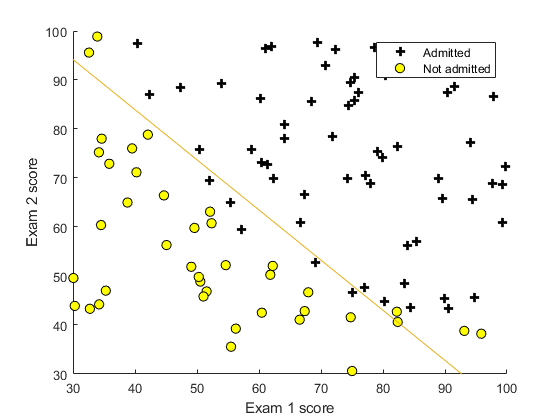


% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

#### 1.2.4 Evaluating logistic regression

After learning the parameters, you can use the model to predict whether a particular student will be admitted. For a student with an Exam 1 score of 45 and an Exam 2 score of 85, you should expect to see an admission probability of 0.776. Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set. In this part, your task is to complete the code in `predict.m`. The predict function will produce '1' or '0' predictions given a dataset and a learned parameter vector $\theta$.

    After you have completed the code in `predict.m`, the code below will proceed to report the training accuracy of your classifier by computing the percentage of examples it got correct. 

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);

    1.2442



fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.776291



% Compute accuracy on our training set
p = predict(theta, X);

   -2.3011
  -10.0717
   -3.0807
    4.6390
    6.3175
   -4.5176
    6.8851
   -0.3095
    8.1454
    1.0221
    2.3097
   -3.5255
    7.2219
    8.8314
   -1.6880
    3.9420
   -0.2912
   -1.7441
    8.1335
    0.2993
   -2.6364
    6.5896
   -4.8964
   -9.1988
    4.8051
    1.7748
    0.4067
    1.8590
   -2.2848
   -4.0677
    2.1657
    3.9461
   -1.6966
   -0.4392
   -2.5249
   -3.3742
    1.7525
    4.3747
   -1.3616
   -2.9533
    3.4865
   -5.0903
    7.5262
    0.0091
   -5.4017
   -1.8402
    4.9536
   12.4755
    7.1363
   11.5921
    6.2676
    7.6014
    2.2542
   -5.8731
   -4.7565
   -2.8852
    8.8499
    0.8175
    4.2188
    5.4515
    7.6658
   -8.4109
   -5.6499
   -8.9707
   -2.5615
   -3.1555
    2.8329
   -4.5880
    9.9536
    0.8920
   -9.6877
    3.7668
    9.1459
    2.0336
    2.2569
   10.0067
    2.4114
    0.5183
   -4.1292
    0.4033
    7.2390
    3.6027
    2.1379
   -1.3665
    9.7387
    6.2039
   -0.5991
    8.6225
   10.5275
   -2.1222
    9.7893

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Regularized logistic regression

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model.

### 2.1 Visualizing the data

Similar to the previous parts of this exercise, `plotData` is used in the code below to generate a figure like Figure 3, where the axes are the two test scores, and the positive ($y=1,$  accepted) and negative ($y=0,$ rejected) examples are shown with different markers. 

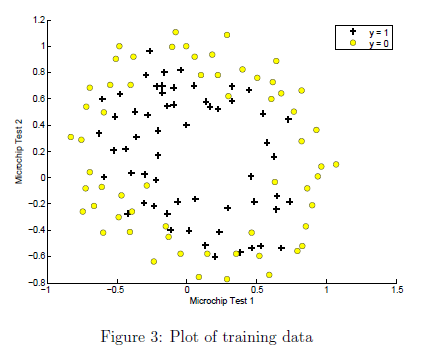

Run the code below and confirm you plot matches Figure 3.

%  The first two columns contains the X values and the third column
%  contains the label (y).
data = load('School Fianance Formatted Data.csv');
X = data(:, [1, 2, 3, 4, 5, 6, 7, 8, 9, 10]); y = data(:, 11);

        Figure 3 shows that our dataset cannot be separated into positive and negative examples by a straight-line through the plot. Therefore, a straightforward application of logistic regression will not perform well on this dataset since logistic regression will only be able to find a linear decision boundary.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. In the provided function `mapFeature.m`, we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\textrm{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \;\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


    As a result of this mapping, our vector of two features (the scores on two QA tests) has been transformed into a 28-dimensional vector. A logistic regression classifier trained on this higher-dimension feature vector will have a more complex decision boundary and will appear nonlinear when drawn in our 2-dimensional plot. 

    Run the code below to map the features.

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

    While the feature mapping allows us to build a more expressive classifier, it also more susceptible to overfitting. In the next parts of the exercise, you will implement regularized logistic regression to fit the data and also see for yourself how regularization can help combat the overfitting problem.

### 2.3 Cost function and gradient

Now you will implement code to compute the cost function and gradient for regularized logistic regression. Complete the code in `costFunctionReg.m` to return the cost and gradient. Recall that the regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that you should not regularize the parameter $\theta_0$. In MATLAB, recall that indexing starts from 1, hence, you should not be regularizing the `theta(1)` parameter (which corresponds to $\theta_0$) in the code. The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:J = (1/m)*sum(-y.*log(h) - (1-y).*log(1-h))+ (lambda/ 2*m )*(theta(2:length(theta)))' * theta(2:length(theta));


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


Once you are done, run the code below to call your `costFunctionReg` function using the initial value of $\theta$ (initialized to all zeros). You should see that the cost is about 0.693.

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



h_theta =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, the next step is to use `fminunc` to learn the optimal parameters. If you have completed the cost and gradient for regularized logistic regression (`costFunctionReg.m`) correctly, you should be able to run the code in the following sections to learn the parameters using `fminunc` for multiple values of $\lambda$.

### 2.4 Plotting the decision boundary

To help you visualize the model learned by this classifier, we have provided the function `plotDecisionBoundary.m` which plots the (nonlinear) decision boundary that separates the positive and negative examples. In `plotDecisionBoundary.m`, we plot the nonlinear decision boundary by computing the classifier's predictions on an evenly spaced grid and then drew a contour plot of where the predictions change from $y = 0$ to $y = 1$. After learning the parameters, the code in the next section will plot a decision boundary similar to Figure 4.

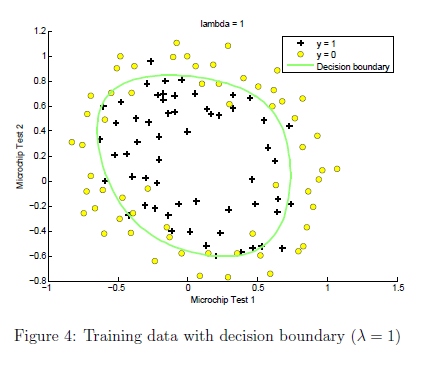

### 2.5 Optional (ungraded) exercises

In this part of the exercise, you will get to try out different regularization parameters for the dataset to understand how regularization prevents overfitting. Notice the changes in the decision boundary as you vary $\lambda$. With a small $\lambda$, you should find that the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data (Figure 5). 

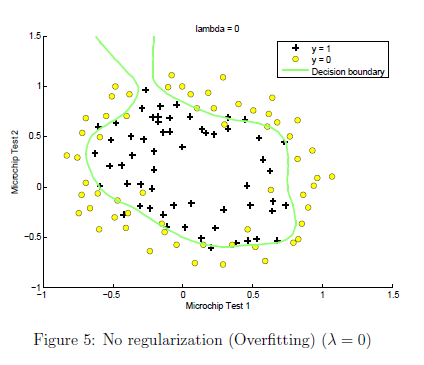

    This is not a good decision boundary: for example, it predicts that a point at $x = (0.25, 1.5)$ is accepted $(y = 1)$, which seems to be an incorrect decision given the training set. With a larger $\lambda$, you should see a plot that shows an simpler decision boundary which still separates the positives and negatives fairly well. However, if $\lambda$ is set to too high a value, you will not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data (Figure 6).

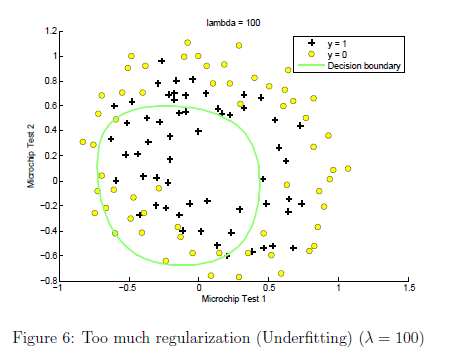

Use the control below to try the following values of $\lambda$: 0, 1, 10, 100. 

- How does the decision boundary change when you vary $\lambda$? 

- How does the training set accuracy vary?

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 100;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



h_theta =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


   -0.0560
   -0.0486
   -0.0484
   -0.0228
   -0.0236
   -0.0138
   -0.0087
   -0.0090
   -0.0142
   -0.0204
   -0.0350
   -0.0468
   -0.0564
   -0.0768
   -0.0649
   -0.0512
   -0.0353
   -0.0850
   -0.0503
   -0.0411
   -0.0416
   -0.0224
   -0.0160
   -0.0126
   -0.0126
   -0.0267
   -0.0405
   -0.0701
   -0.0268
   -0.0699
   -0.1482
   -0.0775
   -0.0405
   -0.0194
   -0.0118
   -0.0071
   -0.0087
   -0.0088
   -0.0107
   -0.0206
   -0.0201
   -0.0344
   -0.0569
   -0.0321
   -0.0577
   -0.0531
   -0.0971
   -0.0368
   -0.0792
   -0.0713
   -0.0384
   -0.0174
   -0.0283
   -0.0125
   -0.0076
   -0.0110
   -0.0067
   -0.0096
   -0.1488
   -0.0868
   -0.0550
   -0.1110
   -0.1226
   -0.0903
   -0.1159
   -0.1655
   -0.1139
   -0.1665
   -0.1521
   -0.1171
   -0.1308
   -0.1141
   -0.1106
   -0.1011
   -0.0691
   -0.0488
   -0.0366
   -0.0332
   -0.0428
   -0.0338
   -0.0238
   -0.0141
   -0.0159
   -0.0116
   -0.0310
   -0.0231
   -0.0318
   -0.0634
   -0.0527
   -0.1249
   -0.1213

h_theta =     0.4860
    0.4879
    0.4879
    0.4943
    0.4941
    0.4966
    0.4978
    0.4978
    0.4964
    0.4949


   -0.0436
   -0.0362
   -0.0360
   -0.0124
   -0.0142
   -0.0066
   -0.0022
   -0.0038
   -0.0096
   -0.0164
   -0.0313
   -0.0433
   -0.0518
   -0.0728
   -0.0554
   -0.0400
   -0.0241
   -0.0717
   -0.0378
   -0.0299
   -0.0316
   -0.0150
   -0.0110
   -0.0085
   -0.0082
   -0.0233
   -0.0369
   -0.0675
   -0.0155
   -0.0569
   -0.1341
   -0.0642
   -0.0284
   -0.0091
   -0.0030
   -0.0004
   -0.0034
   -0.0029
   -0.0044
   -0.0158
   -0.0142
   -0.0286
   -0.0518
   -0.0251
   -0.0508
   -0.0452
   -0.0897
   -0.0259
   -0.0681
   -0.0595
   -0.0269
   -0.0072
   -0.0169
   -0.0029
    0.0005
   -0.0033
   -0.0000
   -0.0045
   -0.1355
   -0.0742
   -0.0436
   -0.0999
   -0.1126
   -0.0807
   -0.1089
   -0.1627
   -0.1090
   -0.1660
   -0.1512
   -0.1147
   -0.1298
   -0.1130
   -0.1100
   -0.1002
   -0.0678
   -0.0458
   -0.0321
   -0.0297
   -0.0410
   -0.0320
   -0.0203
   -0.0101
   -0.0127
   -0.0073
   -0.0296
   -0.0188
   -0.0261
   -0.0534
   -0.0406
   -0.1111
   -0.1081

h_theta =     0.4891
    0.4910
    0.4910
    0.4969
    0.4965
    0.4983
    0.4994
    0.4991
    0.4976
    0.4959


   -0.0331
   -0.0257
   -0.0257
   -0.0024
   -0.0046
    0.0025
    0.0069
    0.0051
   -0.0008
   -0.0078
   -0.0227
   -0.0347
   -0.0428
   -0.0641
   -0.0454
   -0.0297
   -0.0137
   -0.0614
   -0.0274
   -0.0200
   -0.0222
   -0.0060
   -0.0025
   -0.0001
    0.0005
   -0.0148
   -0.0282
   -0.0593
   -0.0052
   -0.0468
   -0.1246
   -0.0539
   -0.0181
    0.0011
    0.0067
    0.0089
    0.0055
    0.0064
    0.0049
   -0.0069
   -0.0049
   -0.0193
   -0.0427
   -0.0155
   -0.0413
   -0.0354
   -0.0804
   -0.0155
   -0.0580
   -0.0492
   -0.0165
    0.0030
   -0.0065
    0.0071
    0.0103
    0.0061
    0.0093
    0.0045
   -0.1259
   -0.0639
   -0.0332
   -0.0901
   -0.1031
   -0.0709
   -0.0998
   -0.1549
   -0.1003
   -0.1586
   -0.1436
   -0.1066
   -0.1221
   -0.1052
   -0.1024
   -0.0925
   -0.0600
   -0.0373
   -0.0232
   -0.0211
   -0.0331
   -0.0241
   -0.0118
   -0.0015
   -0.0046
    0.0013
   -0.0224
   -0.0107
   -0.0179
   -0.0444
   -0.0305
   -0.1015
   -0.0988

h_theta =     0.4917
    0.4936
    0.4936
    0.4994
    0.4989
    0.5006
    0.5017
    0.5013
    0.4998
    0.4981


   -0.0238
   -0.0164
   -0.0164
    0.0075
    0.0053
    0.0129
    0.0176
    0.0160
    0.0103
    0.0033
   -0.0119
   -0.0240
   -0.0323
   -0.0538
   -0.0357
   -0.0200
   -0.0038
   -0.0528
   -0.0182
   -0.0107
   -0.0128
    0.0041
    0.0081
    0.0108
    0.0115
   -0.0039
   -0.0174
   -0.0487
    0.0047
   -0.0380
   -0.1171
   -0.0452
   -0.0086
    0.0111
    0.0170
    0.0197
    0.0165
    0.0173
    0.0159
    0.0041
    0.0060
   -0.0086
   -0.0322
   -0.0049
   -0.0310
   -0.0252
   -0.0708
   -0.0056
   -0.0487
   -0.0399
   -0.0067
    0.0133
    0.0033
    0.0174
    0.0209
    0.0165
    0.0202
    0.0155
   -0.1181
   -0.0551
   -0.0236
   -0.0813
   -0.0943
   -0.0616
   -0.0904
   -0.1455
   -0.0905
   -0.1490
   -0.1339
   -0.0966
   -0.1121
   -0.0950
   -0.0922
   -0.0822
   -0.0494
   -0.0266
   -0.0124
   -0.0103
   -0.0222
   -0.0132
   -0.0008
    0.0095
    0.0064
    0.0122
   -0.0117
   -0.0002
   -0.0078
   -0.0355
   -0.0214
   -0.0938
   -0.0911

h_theta =     0.4940
    0.4959
    0.4959
    0.5019
    0.5013
    0.5032
    0.5044
    0.5040
    0.5026
    0.5008


   -0.0224
   -0.0149
   -0.0149
    0.0095
    0.0075
    0.0157
    0.0206
    0.0192
    0.0135
    0.0066
   -0.0087
   -0.0208
   -0.0294
   -0.0509
   -0.0337
   -0.0183
   -0.0020
   -0.0516
   -0.0167
   -0.0089
   -0.0108
    0.0067
    0.0113
    0.0142
    0.0149
   -0.0005
   -0.0143
   -0.0456
    0.0065
   -0.0367
   -0.1165
   -0.0441
   -0.0070
    0.0131
    0.0195
    0.0226
    0.0196
    0.0204
    0.0188
    0.0072
    0.0089
   -0.0058
   -0.0294
   -0.0023
   -0.0286
   -0.0229
   -0.0687
   -0.0037
   -0.0472
   -0.0384
   -0.0050
    0.0154
    0.0051
    0.0197
    0.0235
    0.0192
    0.0231
    0.0187
   -0.1172
   -0.0538
   -0.0220
   -0.0800
   -0.0928
   -0.0598
   -0.0883
   -0.1430
   -0.0881
   -0.1461
   -0.1310
   -0.0937
   -0.1091
   -0.0919
   -0.0890
   -0.0790
   -0.0461
   -0.0234
   -0.0094
   -0.0070
   -0.0187
   -0.0096
    0.0026
    0.0129
    0.0099
    0.0155
   -0.0079
    0.0030
   -0.0050
   -0.0337
   -0.0199
   -0.0930
   -0.0901

h_theta =     0.4944
    0.4963
    0.4963
    0.5024
    0.5019
    0.5039
    0.5051
    0.5048
    0.5034
    0.5016


   -0.0227
   -0.0152
   -0.0152
    0.0093
    0.0074
    0.0157
    0.0206
    0.0193
    0.0137
    0.0067
   -0.0085
   -0.0207
   -0.0294
   -0.0509
   -0.0340
   -0.0186
   -0.0023
   -0.0521
   -0.0171
   -0.0092
   -0.0110
    0.0067
    0.0115
    0.0144
    0.0150
   -0.0003
   -0.0142
   -0.0455
    0.0063
   -0.0371
   -0.1169
   -0.0445
   -0.0073
    0.0129
    0.0194
    0.0226
    0.0198
    0.0205
    0.0189
    0.0073
    0.0090
   -0.0057
   -0.0294
   -0.0023
   -0.0287
   -0.0231
   -0.0688
   -0.0040
   -0.0475
   -0.0388
   -0.0053
    0.0152
    0.0048
    0.0196
    0.0234
    0.0192
    0.0231
    0.0188
   -0.1176
   -0.0542
   -0.0223
   -0.0803
   -0.0931
   -0.0601
   -0.0885
   -0.1430
   -0.0882
   -0.1459
   -0.1308
   -0.0936
   -0.1090
   -0.0918
   -0.0888
   -0.0788
   -0.0459
   -0.0233
   -0.0093
   -0.0069
   -0.0185
   -0.0093
    0.0028
    0.0131
    0.0102
    0.0157
   -0.0076
    0.0032
   -0.0049
   -0.0339
   -0.0202
   -0.0934
   -0.0905

h_theta =     0.4943
    0.4962
    0.4962
    0.5023
    0.5018
    0.5039
    0.5052
    0.5048
    0.5034
    0.5017


   -0.0228
   -0.0153
   -0.0153
    0.0092
    0.0073
    0.0156
    0.0205
    0.0192
    0.0136
    0.0066
   -0.0086
   -0.0208
   -0.0295
   -0.0510
   -0.0341
   -0.0187
   -0.0024
   -0.0522
   -0.0172
   -0.0093
   -0.0111
    0.0066
    0.0114
    0.0143
    0.0150
   -0.0004
   -0.0142
   -0.0456
    0.0062
   -0.0372
   -0.1170
   -0.0446
   -0.0074
    0.0128
    0.0193
    0.0226
    0.0197
    0.0204
    0.0188
    0.0073
    0.0089
   -0.0058
   -0.0295
   -0.0024
   -0.0288
   -0.0232
   -0.0689
   -0.0041
   -0.0476
   -0.0389
   -0.0054
    0.0151
    0.0047
    0.0195
    0.0234
    0.0191
    0.0230
    0.0187
   -0.1177
   -0.0543
   -0.0224
   -0.0804
   -0.0931
   -0.0602
   -0.0886
   -0.1431
   -0.0882
   -0.1460
   -0.1309
   -0.0937
   -0.1091
   -0.0919
   -0.0889
   -0.0789
   -0.0460
   -0.0234
   -0.0094
   -0.0069
   -0.0185
   -0.0094
    0.0027
    0.0130
    0.0101
    0.0157
   -0.0076
    0.0031
   -0.0049
   -0.0340
   -0.0203
   -0.0935
   -0.0906

h_theta =     0.4943
    0.4962
    0.4962
    0.5023
    0.5018
    0.5039
    0.5051
    0.5048
    0.5034
    0.5017


   -0.0228
   -0.0154
   -0.0153
    0.0092
    0.0073
    0.0156
    0.0205
    0.0192
    0.0136
    0.0066
   -0.0086
   -0.0208
   -0.0295
   -0.0510
   -0.0341
   -0.0187
   -0.0024
   -0.0522
   -0.0172
   -0.0093
   -0.0111
    0.0066
    0.0114
    0.0143
    0.0149
   -0.0004
   -0.0143
   -0.0456
    0.0062
   -0.0372
   -0.1170
   -0.0446
   -0.0074
    0.0128
    0.0193
    0.0225
    0.0197
    0.0204
    0.0188
    0.0073
    0.0089
   -0.0058
   -0.0295
   -0.0024
   -0.0288
   -0.0232
   -0.0689
   -0.0041
   -0.0476
   -0.0389
   -0.0054
    0.0151
    0.0047
    0.0195
    0.0233
    0.0191
    0.0230
    0.0187
   -0.1177
   -0.0543
   -0.0224
   -0.0804
   -0.0931
   -0.0602
   -0.0886
   -0.1431
   -0.0882
   -0.1460
   -0.1309
   -0.0937
   -0.1091
   -0.0919
   -0.0889
   -0.0789
   -0.0460
   -0.0234
   -0.0094
   -0.0069
   -0.0186
   -0.0094
    0.0027
    0.0130
    0.0101
    0.0156
   -0.0076
    0.0031
   -0.0049
   -0.0340
   -0.0203
   -0.0935
   -0.0906

h_theta =     0.4943
    0.4962
    0.4962
    0.5023
    0.5018
    0.5039
    0.5051
    0.5048
    0.5034
    0.5017



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


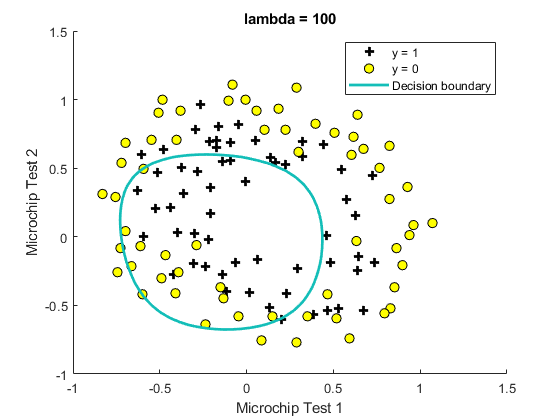

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


% Compute accuracy on our training set
p = predict(theta, X);

   -0.0228
   -0.0154
   -0.0153
    0.0092
    0.0073
    0.0156
    0.0205
    0.0192
    0.0136
    0.0066
   -0.0086
   -0.0208
   -0.0295
   -0.0510
   -0.0341
   -0.0187
   -0.0024
   -0.0522
   -0.0172
   -0.0093
   -0.0111
    0.0066
    0.0114
    0.0143
    0.0149
   -0.0004
   -0.0143
   -0.0456
    0.0062
   -0.0372
   -0.1170
   -0.0446
   -0.0074
    0.0128
    0.0193
    0.0225
    0.0197
    0.0204
    0.0188
    0.0073
    0.0089
   -0.0058
   -0.0295
   -0.0024
   -0.0288
   -0.0232
   -0.0689
   -0.0041
   -0.0476
   -0.0389
   -0.0054
    0.0151
    0.0047
    0.0195
    0.0233
    0.0191
    0.0230
    0.0187
   -0.1177
   -0.0543
   -0.0224
   -0.0804
   -0.0931
   -0.0602
   -0.0886
   -0.1431
   -0.0882
   -0.1460
   -0.1309
   -0.0937
   -0.1091
   -0.0919
   -0.0889
   -0.0789
   -0.0460
   -0.0234
   -0.0094
   -0.0069
   -0.0186
   -0.0094
    0.0027
    0.0130
    0.0101
    0.0156
   -0.0076
    0.0031
   -0.0049
   -0.0340
   -0.0203
   -0.0935
   -0.0906


fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 61.016949


*You do not need to submit any solutions for these optional (ungraded) exercises.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the `submit` function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

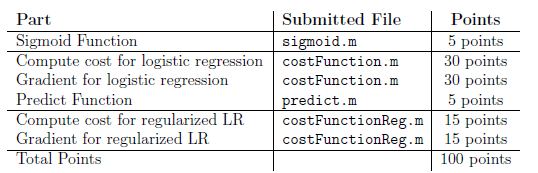

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.